# 有限冲激响应数字滤波器设计

## 7.4(1) 窗函数法设计滤波器

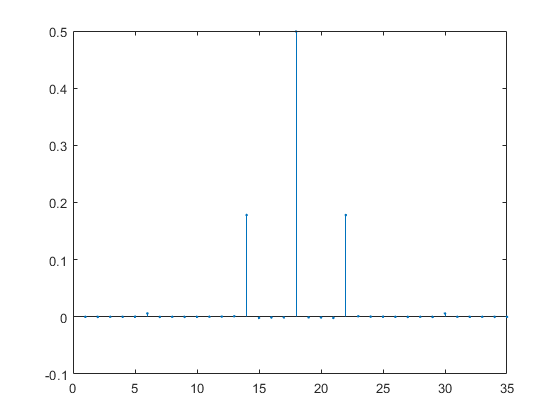

N=33;

F1=0:0.01:0.25;
A1=-4*F1+1;


F2=0.26:0.01:0.5;
A2=4*F2-1;

F3=0.51:0.01:0.75;
A3=-4*F3+3;

F4=0.76:0.01:1;
A4=4*F4-3;

F=[F1 F2 F3 F4];
A=[A1 A2 A3 A4];

ham=fir2(N+1,F,A);
stem(ham,'.');

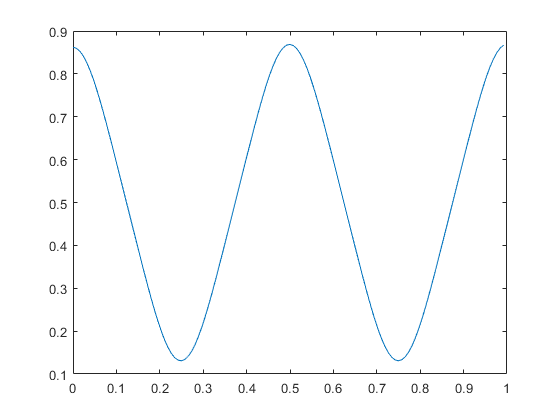

[h1,w]=freqz(ham,1,128,1);
plot([0:127]/128,abs(h1));

## 7.4(2) 频率抽样法设计滤波器

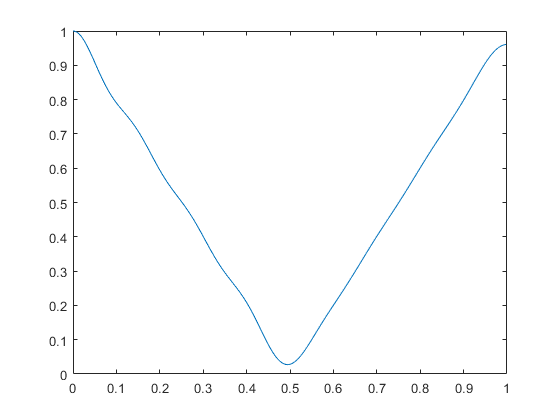

Hd=[];
for k=0:32
    if(k<=8)
        Hd(k+1)=(-4/33*k+1)*exp((-1j*k*pi*(N-1))/N);
    end
    if(k>=9&&k<=16)
        Hd(k+1)=(4/33*k-1)*exp((-1j*k*pi*(N-1))/N);
    end
    if(k>=17&&k<=24)
        Hd(k+1)=(-4/33*k+3)*exp((-1j*k*pi*(N-1))/N);
    end
    if(k>=25&&k<=32)
        Hd(k+1)=(4/33*k-3)*exp((-1j*k*pi*(N-1))/N);
    end
end

h=ifft(Hd);
H=freqz(h,1);
plot([0:1:511]/512,abs(H));